# Part 1 

for x = 1:20
    I = imread(sprintf('Images/s%d.JPG', x));
    BW = roipoly(I);
    figures
    BW = imresize(BW, [275 183]);
    imshow(BW);
    save(sprintf('Output/s%d_mask.mat', x), 'BW');
end

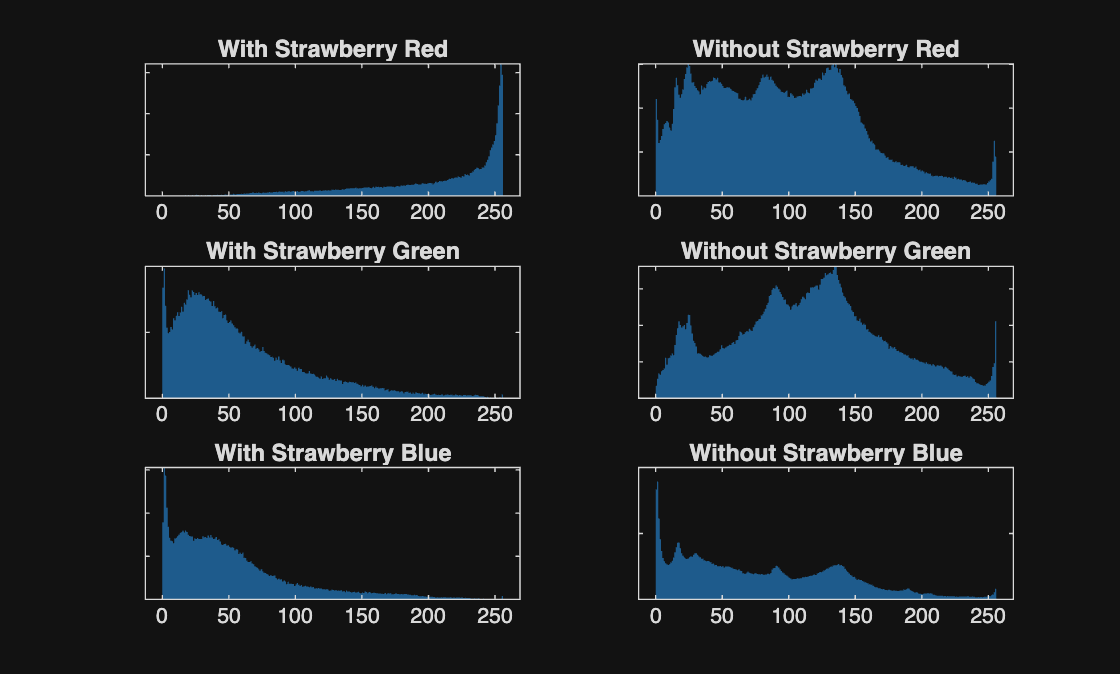

I_straw = zeros(256,3);
I_no_straw = zeros(256,3);
for x = 1:20
    I = imread(sprintf('Images/s%d.JPG', x));
    I = imresize(I, [275 183]);
    mask = load(sprintf('Output/s%d_mask.mat', x));
    mask = mask.BW;

    for RGB = 1:3
        I_RGB = I(:,:,RGB);
        I_straw(:,RGB)    = I_straw(:,RGB)    + histcounts(I_RGB(mask),  0:256).';
        I_no_straw(:,RGB) = I_no_straw(:,RGB) + histcounts(I_RGB(~mask), 0:256).';
    end
    R = I(:,:,1);
    [N,edges] = histcounts(R(mask),  0:256);
end

RGB_title= ["Red", "Green", "Blue"];
for i  = 1:3
    subplot(3,2,2*i-1)
    histogram('BinEdges', edges, 'BinCounts', I_straw(:,i), 'EdgeColor', 'none');
    title("With Strawberry "+RGB_title(i))
    set(gca, 'YTickLabel', []);
    subplot(3,2,2*i)
    histogram('BinEdges', edges, 'BinCounts', I_no_straw(:,i), 'EdgeColor', 'none');
    title("Without Strawberry "+RGB_title(i))
    set(gca, 'YTickLabel', []);
end

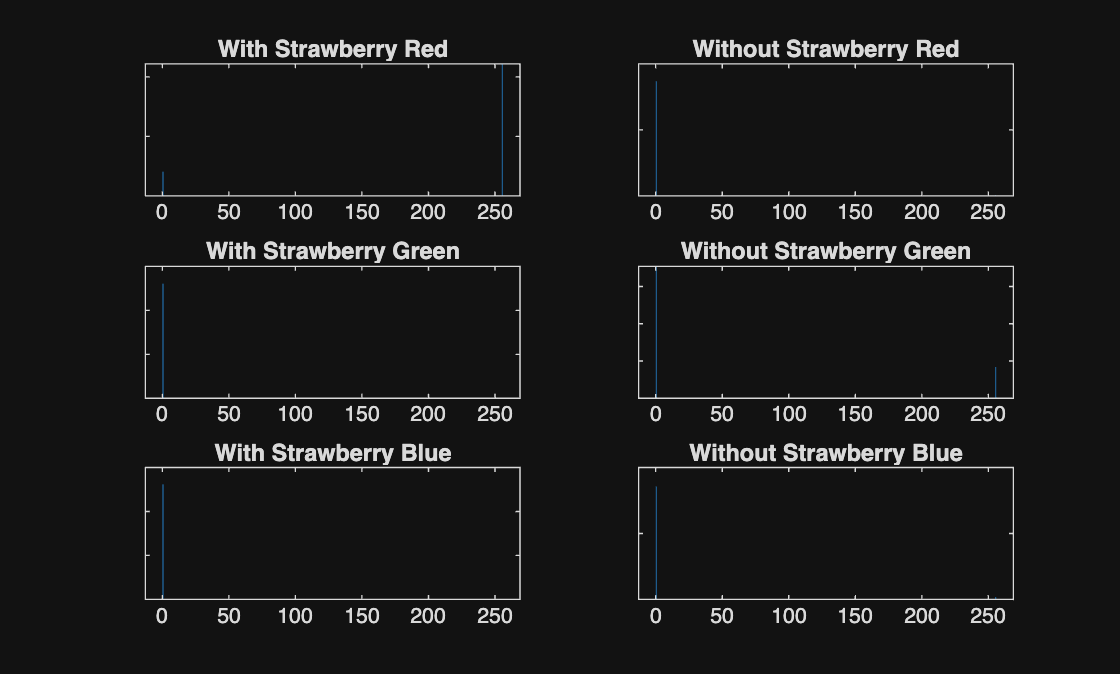

clear;
clc;
close all;

I_straw = zeros(256,3);
I_no_straw = zeros(256,3);
for x = 1:20
    I = imread(sprintf('Images/s%d.JPG', x));
    I = imresize(I, [275 183]);
    mask = load(sprintf('Output/s%d_mask.mat', x));
    mask = mask.BW;

    for x_pixel = 1:275
        for y_pixel = 1:183
            total = sum(I(x_pixel,y_pixel,:));
            I(x_pixel,y_pixel,1) = (I(x_pixel,y_pixel,1)/total)*255;
            I(x_pixel,y_pixel,2) = (I(x_pixel,y_pixel,2)/total)*255;
            I(x_pixel,y_pixel,3) = (I(x_pixel,y_pixel,3)/total)*255;
        end
    end


    for RGB = 1:3
        I_RGB = I(:,:,RGB);
        I_straw(:,RGB)    = I_straw(:,RGB)    + histcounts(I_RGB(mask),  0:256).';
        I_no_straw(:,RGB) = I_no_straw(:,RGB) + histcounts(I_RGB(~mask), 0:256).';
    end
    R = I(:,:,1);
    [N,edges] = histcounts(R(mask),  0:256);
end

RGB_title= ["Red", "Green", "Blue"];
for i  = 1:3
    subplot(3,2,2*i-1)
    histogram('BinEdges', edges, 'BinCounts', I_straw(:,i), 'EdgeColor', 'none');
    title("With Strawberry "+RGB_title(i))
    set(gca, 'YTickLabel', []);

    subplot(3,2,2*i)
    histogram('BinEdges', edges, 'BinCounts', I_no_straw(:,i), 'EdgeColor', 'none');
    title("Without Strawberry "+RGB_title(i))
    set(gca, 'YTickLabel', []);
end